# Storytelling with Data: Predict Cases Based on Time, Location, and Mask Usage

## Prep data for modeling

Load the data from previous steps if not already in workspace 

load mergedCountyData.mat
load allCountyData.mat 

Convert data for machine learning

To capture the time, we will use the day of year (works for 2020), to keep a sequential numeric.

We will use lat/lon for location and the mask usage values by county.

data = timetable2table(allCountyData);
data.dayvalue = data.date - datetime(2020,1,1);
data.dayvalue = days(data.dayvalue);
vars = ["dayvalue","cases","state","POPESTIMATE2019","LON","LAT",... 
    "NEVER","RARELY","SOMETIMES","FREQUENTLY","ALWAYS"]; 
tdata = data(:,vars);

Split data (significantly maybe, to make training go faster), leaving some out to test. We can start small, with fewer data points to get a sense and work our way up gradually to a larger data set for training.

% Use rng for repeatable split for testing
rng(1234)

% Split based on percentage (80/20) 
cv = cvpartition(allCountyData.state,"HoldOut",0.8);

trainData = tdata(training(cv),:);
testData = tdata(test(cv),:);

save Data/trainData.mat trainData testData

## Regression models

Use the Regresion Learner app to explore many models for this data.

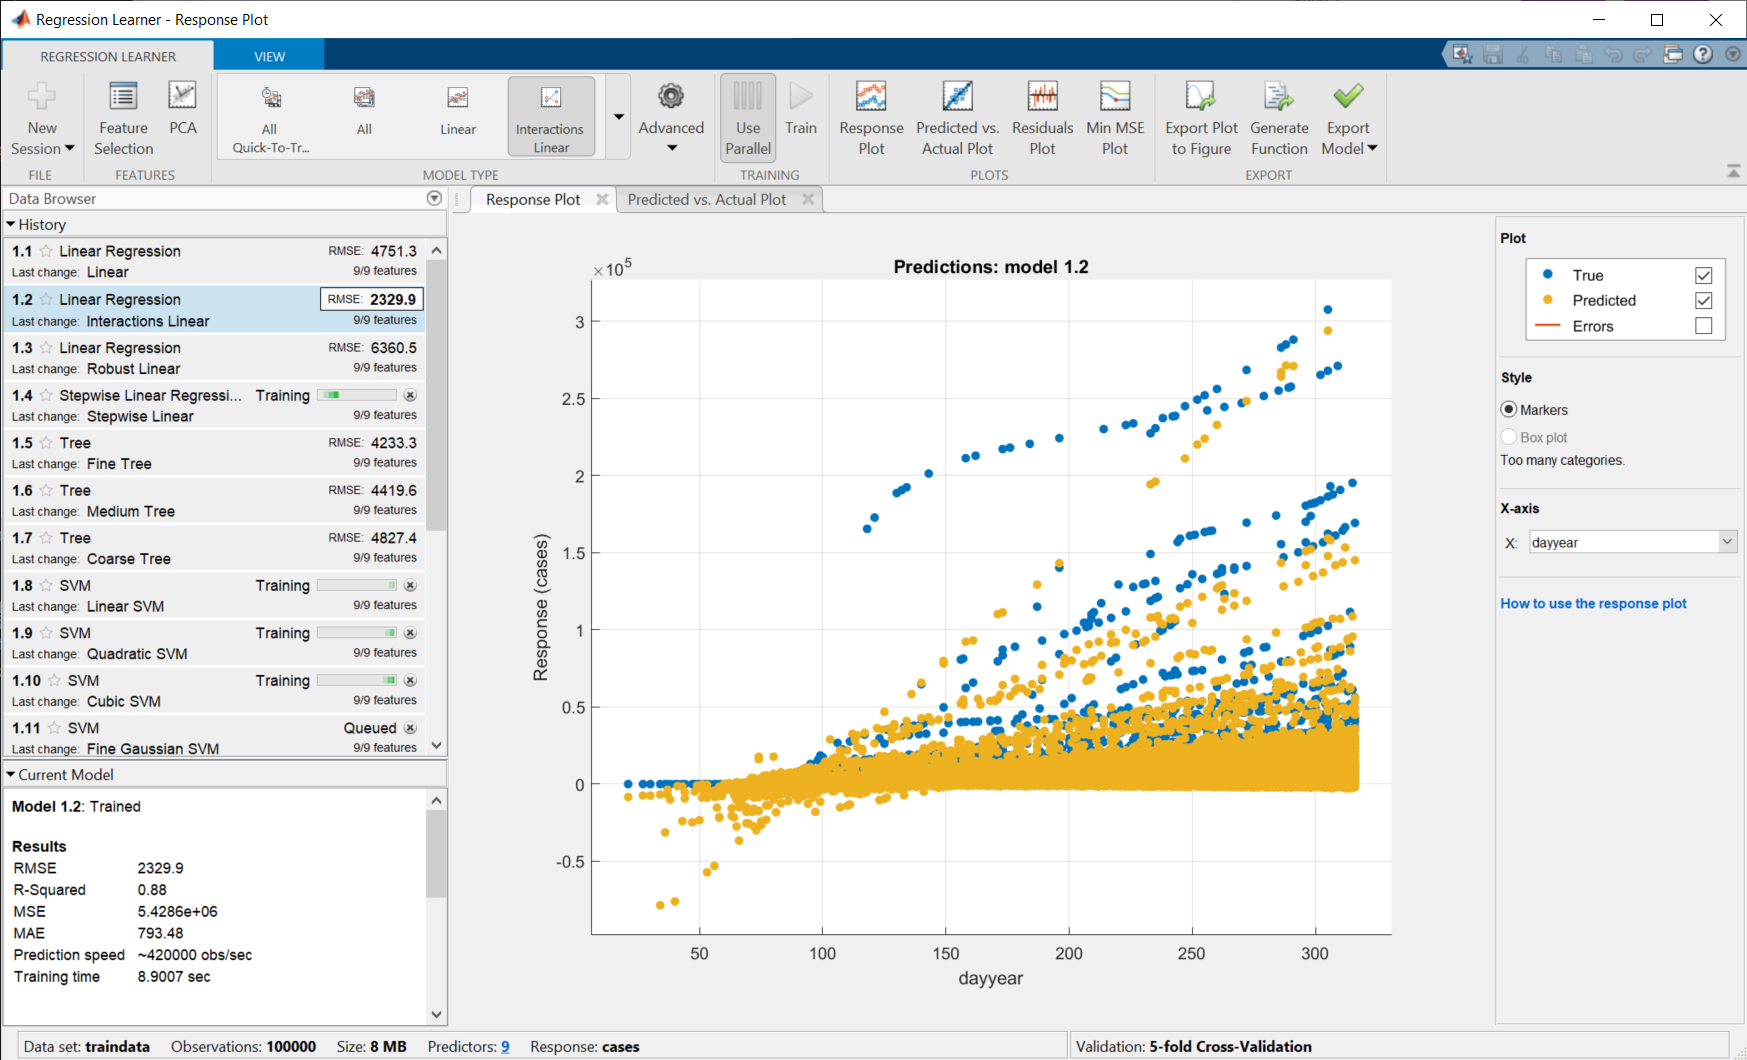

Workflow:

- Load the training data into the app

- Response is cases

- Try different models

- Use visuals and model info to assess

- Save model(s) that predict best to you

- Predict with remaining data (outside of app)

The models were previously trained and saved as a .mat file.

load("trainedRegModels.mat")

## Explore model results

Interactions model looked good and linear models are great for exploring relationships.

linIntModel = linearInteractions.LinearModel;
linModel = linearModel.LinearModel

linModel = Linear regression model:
    cases ~ 1 + dayyear + POPESTIMATE2019 + LON + LAT + NEVER + RARELY + SOMETIMES + FREQUENTLY + ALWAYS

Estimated Coefficients:
                        Estimate          SE         tStat       pValue  
                       ___________    __________    _______    __________
    (Intercept)         1.3921e+05         24075     5.7823    7.3925e-09
    dayyear                 16.759       0.23519     71.257             0
    POPESTIMATE2019       0.012488    4.5232e-05     276.08             0
    LON                     21.959        1.3893     15.806     3.352e-56
    LAT                    -38.593        3.4222    -11.277    1.7775e-29
    NEVER              -1.3822e+05         24065    -5.7436    9.2974e-09
    

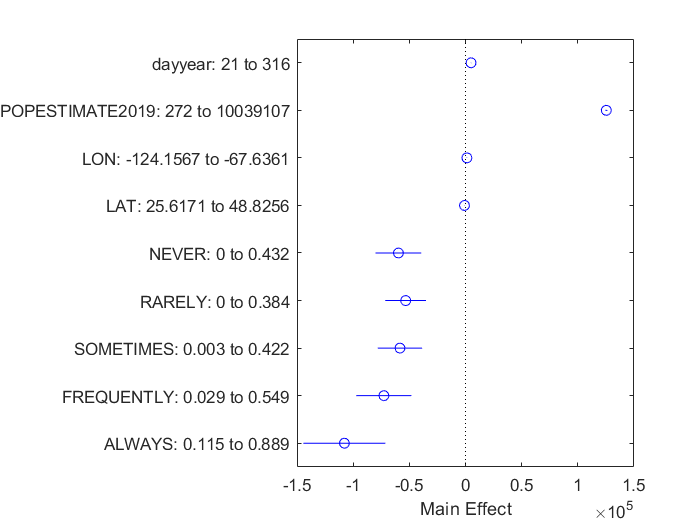

plotEffects(linModel)

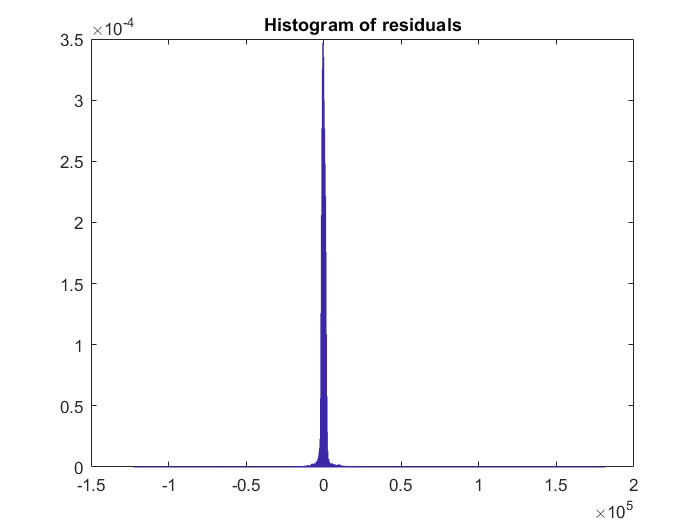

plotResiduals(linModel)

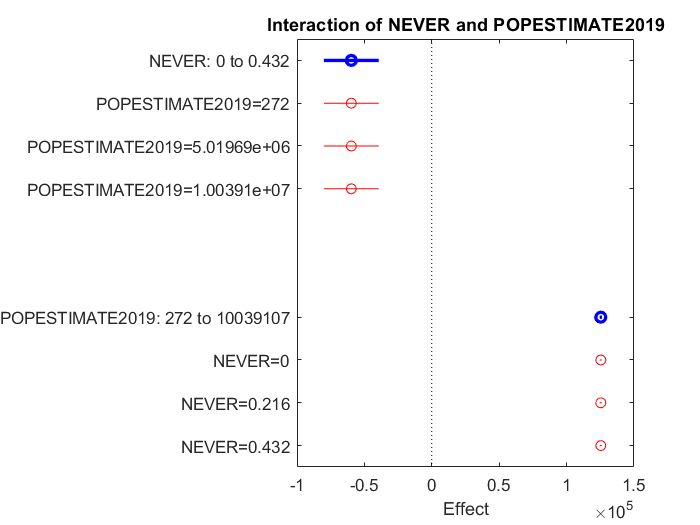

plotInteraction(linModel,"NEVER","POPESTIMATE2019")

linIntModel

linIntModel = Linear regression model:
    cases ~ 1 + dayyear*POPESTIMATE2019 + dayyear*LON + dayyear*LAT + dayyear*NEVER + dayyear*RARELY + dayyear*SOMETIMES + dayyear*FREQUENTLY + dayyear*ALWAYS + POPESTIMATE2019*LON + POPESTIMATE2019*LAT + POPESTIMATE2019*NEVER + POPESTIMATE2019*RARELY + POPESTIMATE2019*SOMETIMES + POPESTIMATE2019*FREQUENTLY + POPESTIMATE2019*ALWAYS + LON*LAT + LON*NEVER + LON*RARELY + LON*SOMETIMES + LON*FREQUENTLY + LON*ALWAYS + LAT*NEVER + LAT*RARELY + LAT*SOMETIMES + LAT*FREQUENTLY + LAT*ALWAYS + NEVER*RARELY + NEVER*SOMETIMES + NEVER*FREQUENTLY + NEVER*ALWAYS + RARELY*SOMETIMES + RARELY*FREQUENTLY + RARELY*ALWAYS + SOMETIMES*FREQUENTLY + SOMETIMES*ALWAYS + FREQUENTLY*ALWAYS

Estimated Coefficients:
                                   Estimate          SE         tStat        pValue   
                                  ___________    __________    ______

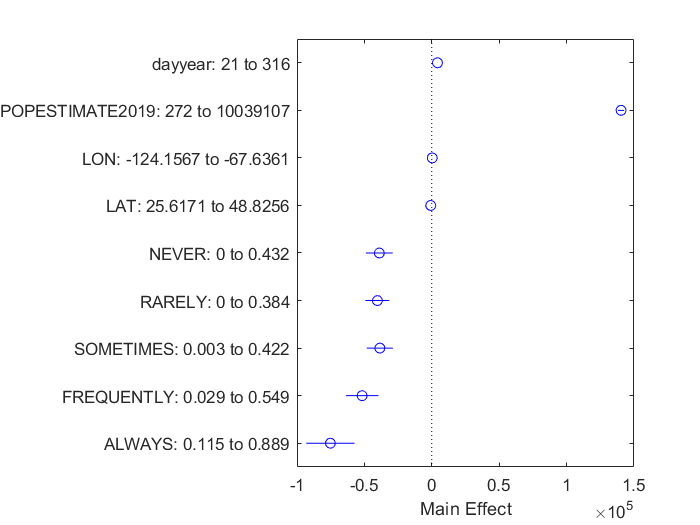

plotEffects(linIntModel)

## Test predictions

Create the data in the same way the data was arranged for model training.

load expGPRnew.mat
cty = "Suffolk"; 
st = "Massachusetts";
idx = allCountyData.county == cty & allCountyData.state == st;
thiscounty = timetable2table(allCountyData(idx,:));
thiscounty.dayvalue = thiscounty.date - datetime(2020,1,1);
thiscounty.dayvalue = days(thiscounty.dayvalue);
thiscounty.state = removecats(thiscounty.state);
thiscounty.county = removecats(thiscounty.county);
vars = ["dayvalue","cases","POPESTIMATE2019","LON","LAT",... 
    "NEVER","RARELY","SOMETIMES","FREQUENTLY","ALWAYS"]; 
predcases = predict(regressionGP,thiscounty(:,vars));                    %#ok

Create a function to do the prediction and create a plot of the actual and predicted values.

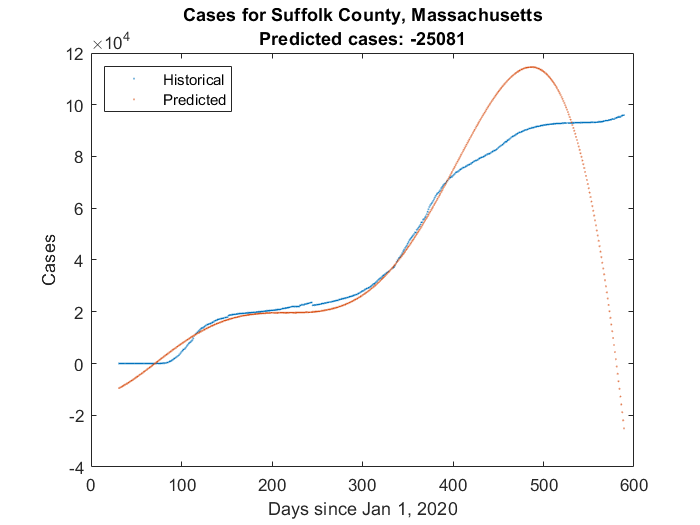

[predcases,thiscounty] = predictAndPlot(regressionGP,allCountyData,cty,st);  %#ok

Test all data points.

% pcases = predict(regressionGP,testData);  % takes awhile!

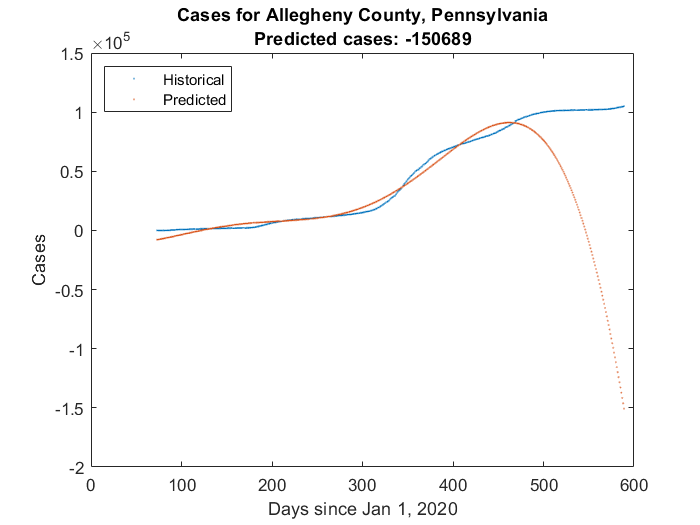

figure
[predcases,thiscounty] = predictAndPlot(regressionGP,allCountyData,...                                 %#ok
    "Allegheny","Pennsylvania");                                                               %#ok<ASGLU> 
figure
[predcases,thiscounty] = predictAndPlot(regressionGP,allCountyData,...

    "Norfolk","Massachusetts");

## App: Integrate predictions

Some predictions are not as good. We could predict for all counties and explore those with large differences in current values to perhaps understand. 

We can also spend time tuning the model (even in the app!) However, the quality is not as crucial in our case, so we will move on for now and use this to communicate the information.

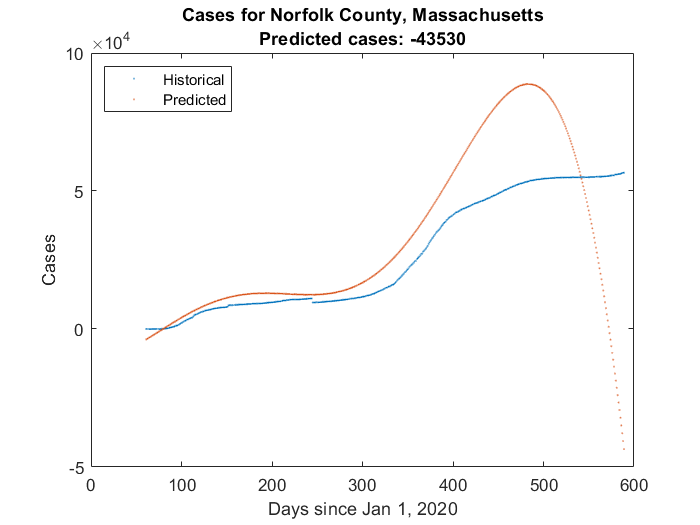

edit CommunicationDataSci.mlx

**Helper functions**

function [predcases,thiscounty] = predictAndPlot(regressionGP,allCountyData,cty,st)
idx = allCountyData.county == cty & allCountyData.state == st;
thiscounty = timetable2table(allCountyData(idx,:));
thiscounty.dayvalue = thiscounty.date - datetime(2020,1,1);
thiscounty.dayvalue = days(thiscounty.dayvalue);
thiscounty.state = removecats(thiscounty.state);
thiscounty.county = removecats(thiscounty.county);
vars = ["dayvalue","cases","POPESTIMATE2019","LON","LAT",... 
    "NEVER","RARELY","SOMETIMES","FREQUENTLY","ALWAYS"]; 
predcases = predict(regressionGP,thiscounty(:,vars));


figure
plot(thiscounty.dayvalue,thiscounty.cases,'.','MarkerSize',0.2)
hold on
plot(thiscounty.dayvalue,predcases,'.','MarkerSize',0.2)
hold off
legend("Historical","Predicted","Location","northwest")
title(["Cases for "+cty+" County, "+st,...
    "Predicted cases: "+string(floor(predcases(end)))])
ylabel("Cases")
xlabel("Days since Jan 1, 2020")
end